# Aircraft Conflict Resolution

syms x_i y_i r t real
syms v omega real

assume( abs(v) > 1 & abs(x_i)>1 & abs(y_i)>1 & abs(omega)>1 )

r = 3;
v = 5;
omega = 1;

v1 = v;
v2 = v;
omega_1 = omega;
omega_2 = omega;

r_turn = v/omega;       % turning radiu
v_slope = v2/v1;        % slope of velocity seen from relative system

## Initial conditions

phi = pi/2;
init_state = [x_i; y_i];

## State equations

% state q1: velocity
xr_dot_q1 = -v1 + v2*cos(phi);
yr_dot_q1 = v2*sin(phi);
phi_dot_q1 = 0;

%state q1: position
x_r = int(xr_dot_q1, t) + init_state(1);
y_r = int(yr_dot_q1, t) + init_state(2);

% state q2: velocity
xr_dot_q2 = xr_dot_q1 + omega_1*(y_r - init_state(2));
yr_dot_q2 = yr_dot_q1 - omega_2*(x_r - init_state(1));
phi_dot_q2 = omega_1 - omega_2;

%state q2: position
xr_q2 = int(xr_dot_q2, t) + init_state(1);
yr_q2 = int(yr_dot_q2, t) + init_state(2);

state_q1 = [xr_dot_q1; yr_dot_q1; phi_dot_q1];
state_q2 = [xr_dot_q2; yr_dot_q2; phi_dot_q2];
state_q3 = state_q1;

## Condition enter the unsafe region

trigger = x_r^2 + y_r^2 - r^2;

expanded_eq = expand(trigger);
trig_coefs = coeffs(expanded_eq, t, 'All');
a = trig_coefs(1);
b = trig_coefs(2);
c = trig_coefs(3);

% Given v and r, we will have problem in choosing initial condition
delta = simplify( b^2 - 4*a*c >= 0 ) % condition for collision

$$delta = {\left(y_{i}+x_{i}\right)}^{2}\leq 18$$

## Time to switch in state q2: forced manuver

q1_time_trigger_sym = solve(trigger == 0, t);

q1_time_trigger = min( subs(q1_time_trigger_sym, [v1 v2 r x_i y_i], [5 5 5 7 -3]) ); % 33 instead of -3, no collision

if  imag(q1_time_trigger) 
    disp("There is no collision")
else
    fprintf("Collision after %f seconds from start", q1_time_trigger)
end

Collision after 0.858579 seconds from start

## Time to switch in state q3

half_circle_eqn = omega*t == pi;
sol_time_trigger_q23 = solve(half_circle_eqn, t)

$$sol\_time\_trigger\_q23 = 3.1416$$

%time_trigger_q23 = subs(sol_time_trigger_q23, [omega_1 omega_2], [1 1]);

fprintf("Time to switch from state q2 to q3: %f seconds", sol_time_trigger_q23)

Time to switch from state q2 to q3: 3.141593 seconds

## Alert region: can't start manuver

r_alert_small = r - 2*r_turn;
r_alert_big = -r - 2*r_turn;



## Plot zones

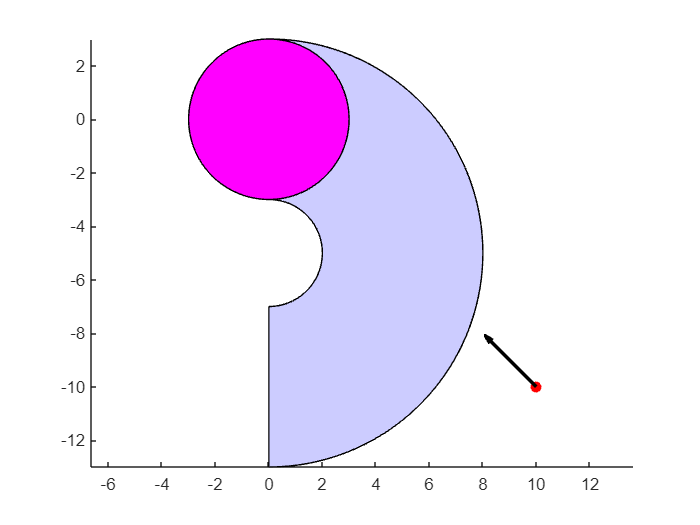

% Define the radii and center adjustments
r_small = 3;
r_turn = 5;

r_medium = (2*r_turn - 2*r_small)/2;
r_big = (2*r_small + 2*r_turn)/2;

shift = r_medium/2;

% Define centers
center_small = [0, 0];
center_medium = [0, -(  ((2*r_turn - 2*r_small)/2) + r_small   ) ];
center_big = center_medium;

% Plot the small circle
theta = linspace(0, 2*pi, 100);
x_small = r_small * cos(theta) + center_small(1);
y_small = r_small * sin(theta) + center_small(2);
figure;

hold on;

% Plot only the right side of the annular region
theta_right = linspace(-pi/2, pi/2, 100); % Half circle on the right
x_big_upper = r_big * cos(theta_right) + center_big(1);
y_big_upper = r_big * sin(theta_right) + center_big(2);
x_medium_upper = r_medium * cos(theta_right) + center_medium(1);
y_medium_upper = r_medium * sin(theta_right) + center_medium(2);

% Plot the upper half of the annular region
fill([x_big_upper, fliplr(x_medium_upper)], [y_big_upper, fliplr(y_medium_upper)], [0.8, 0.8, 1]);
fill(x_small, y_small, 'm'); % 'm' for magenta (violet)

plot(10, -10, 'ro', 'MarkerFaceColor', 'r')

length = 3; % Length of the arrow

% Calculate the components of the arrow
dx = length / sqrt(1 + v_slope^2);
dy = -v_slope * dx;

% Plot the arrow
quiver(10, -10, -dx, -dy, 'k', 'LineWidth', 2, 'MaxHeadSize', 0.5);


% Set the axis properties and display
axis equal;
%xlim([-15, 15]);
%ylim([-15, 15]);
hold off;